# Supermileage Vehicle Simulation

[**Documentation**](https://docs.google.com/document/d/1g9IYxAuLaUAbttDUqafE3u3H9sW9519EXk1D3lMdIaE/edit?usp=sharing)

Author: Ambrose Lee  

Last Updated: Aug 22, 2020

### Instructions

- Set desired vehicle/motor parameters and input parameters in the Parameters.m file

- Select simulation to run below (Urban / FCV, Regular / Monte Carlo)

### Simulation Results

- Total Time: the total time to complete full run, in minutes

- Mileage1: mileage calculated from torque input, in m/kWh

- Mileage2: mileage calculated from interpolated power output, in m/kWh

- Mileage3: mileage calculated from actual power output, in m/kWh

- Total Braking Energy: total energy wasted due to braking, in J

## Urban Concept Regular Simulation

% Load Input Parameters
run Parameters.m;
S = load('Urban_Input.mat');
[mileage1, mileage2, mileage3, totalTime, brakeEnergy] = runUrban(S.max_velocity,S.brake_distance,S.initialOutput, S.plot_fig)

mileage1 = 132.1161

mileage2 = 139.5683

mileage3 = 132.1161

totalTime = 25.7480

brakeEnergy = 796.7569

## Urban Concept Monte Carlo Simulation

% Load Input Parameters
run Parameters.m;
S = load('Urban_Input.mat');
[T] = runUrbanMC(S.maxV_mean, S.maxV_sd, S.brakeDist_mean, S.brakeDist_sd, S.initialOutput_mean, S.initialOutput_sd,S.numTrials, S.generateHistogram)

## FCV Regular Simulation

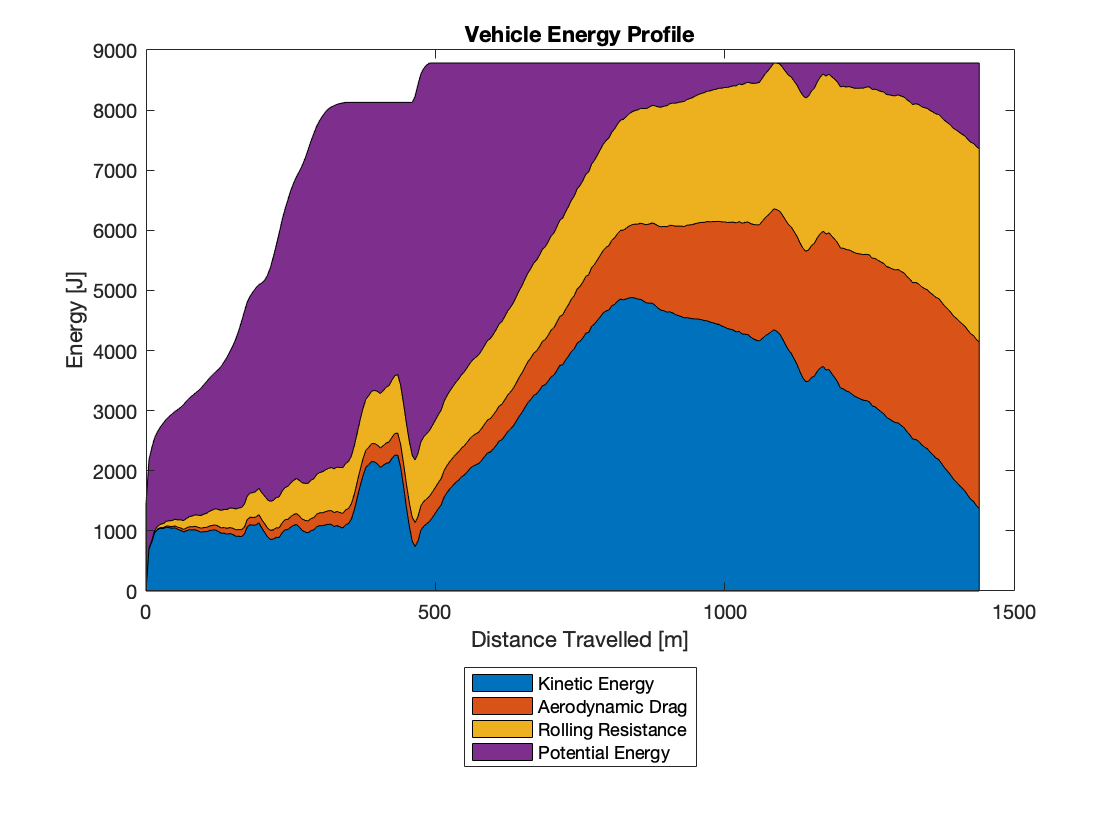

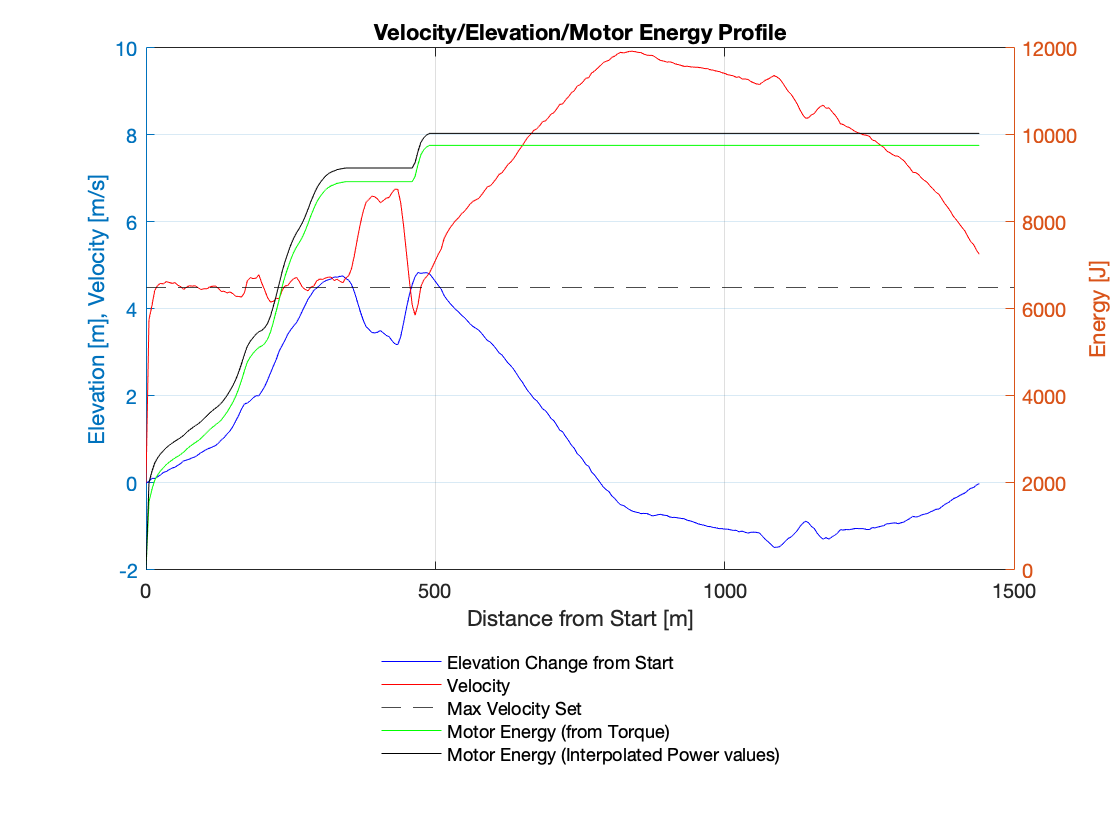

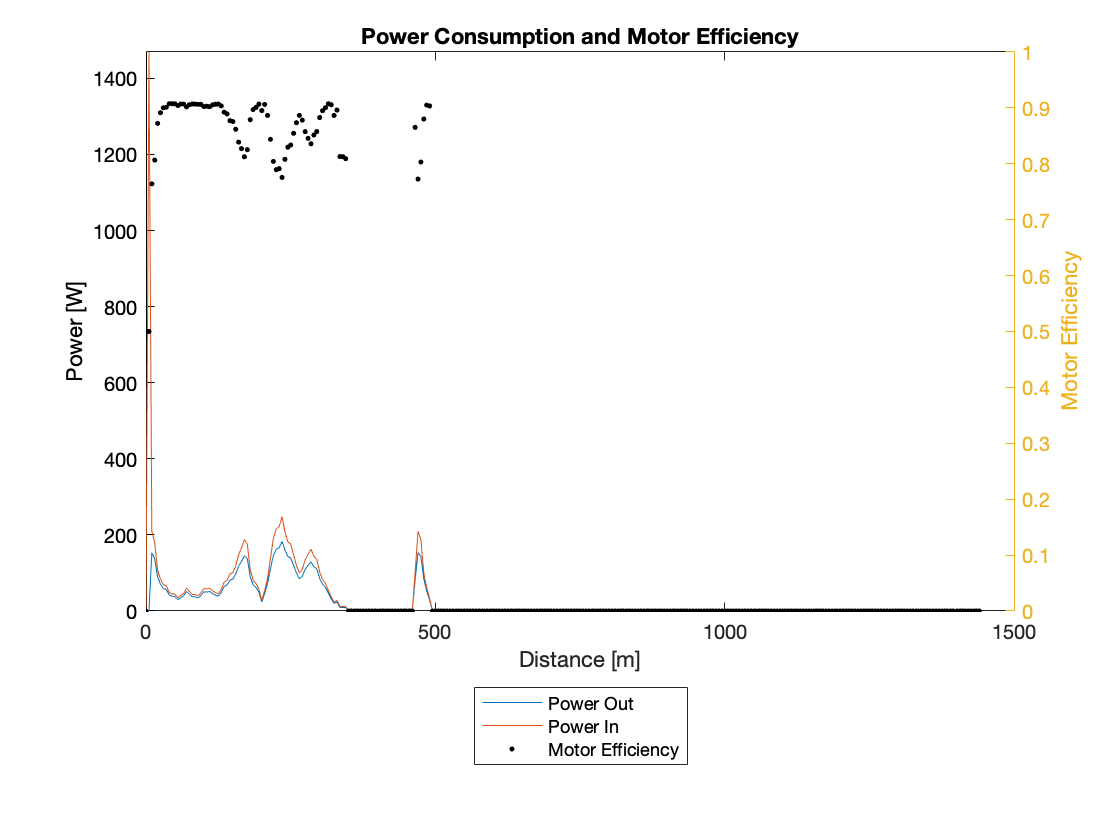

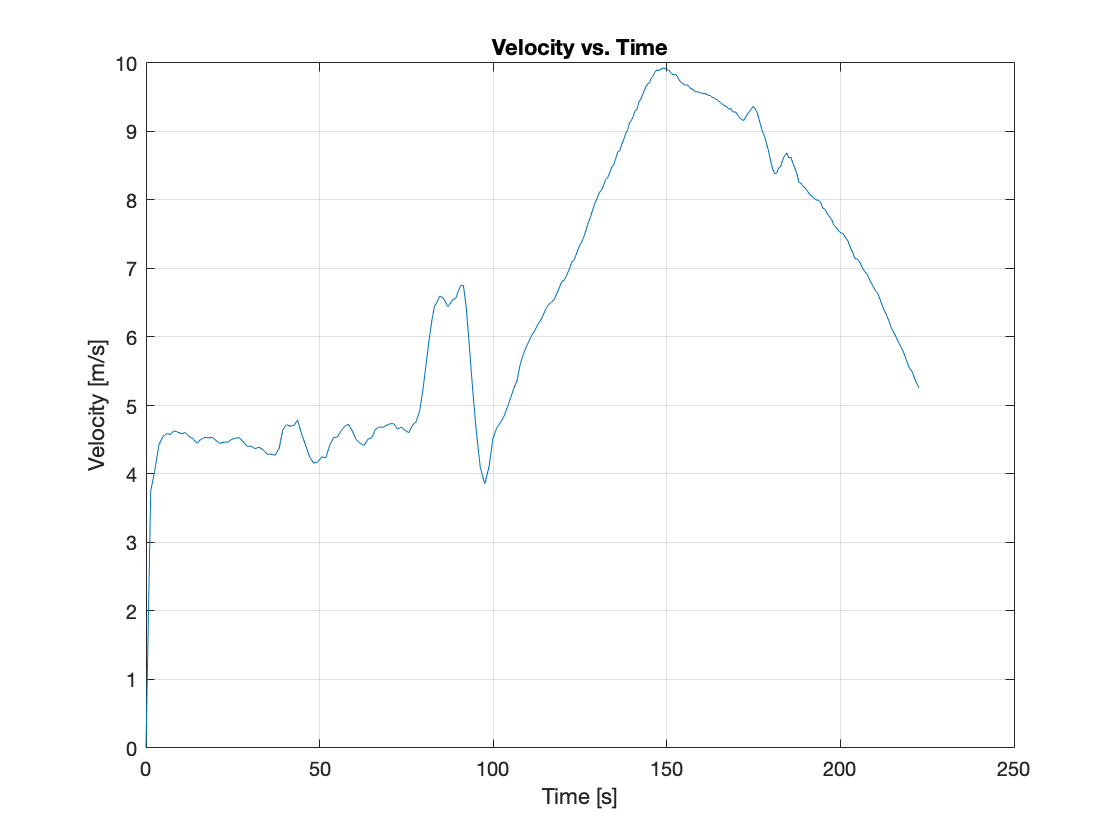

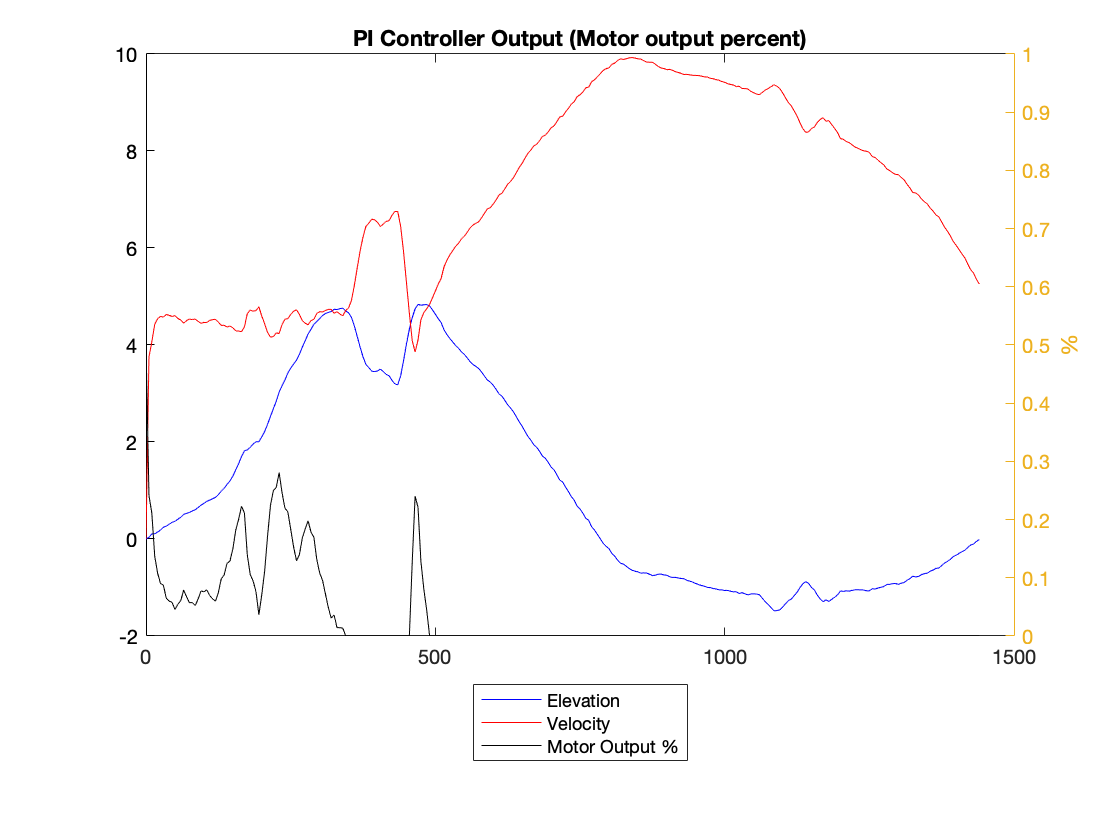

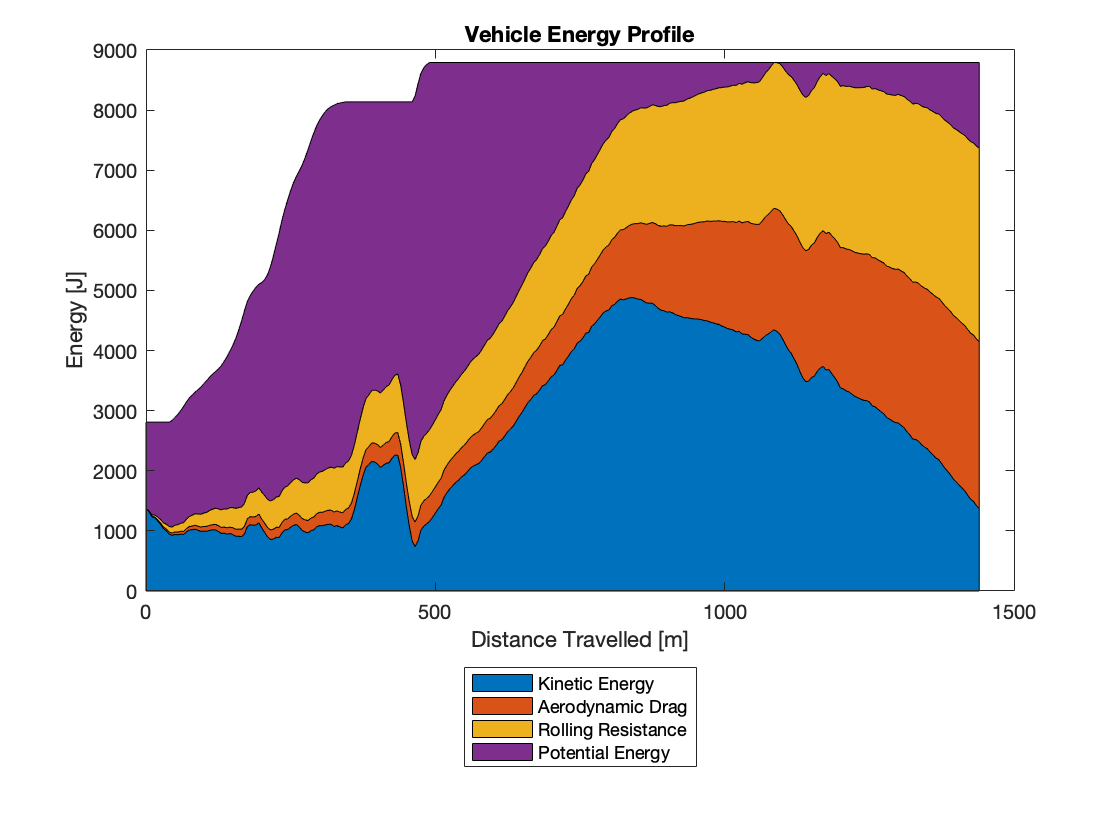

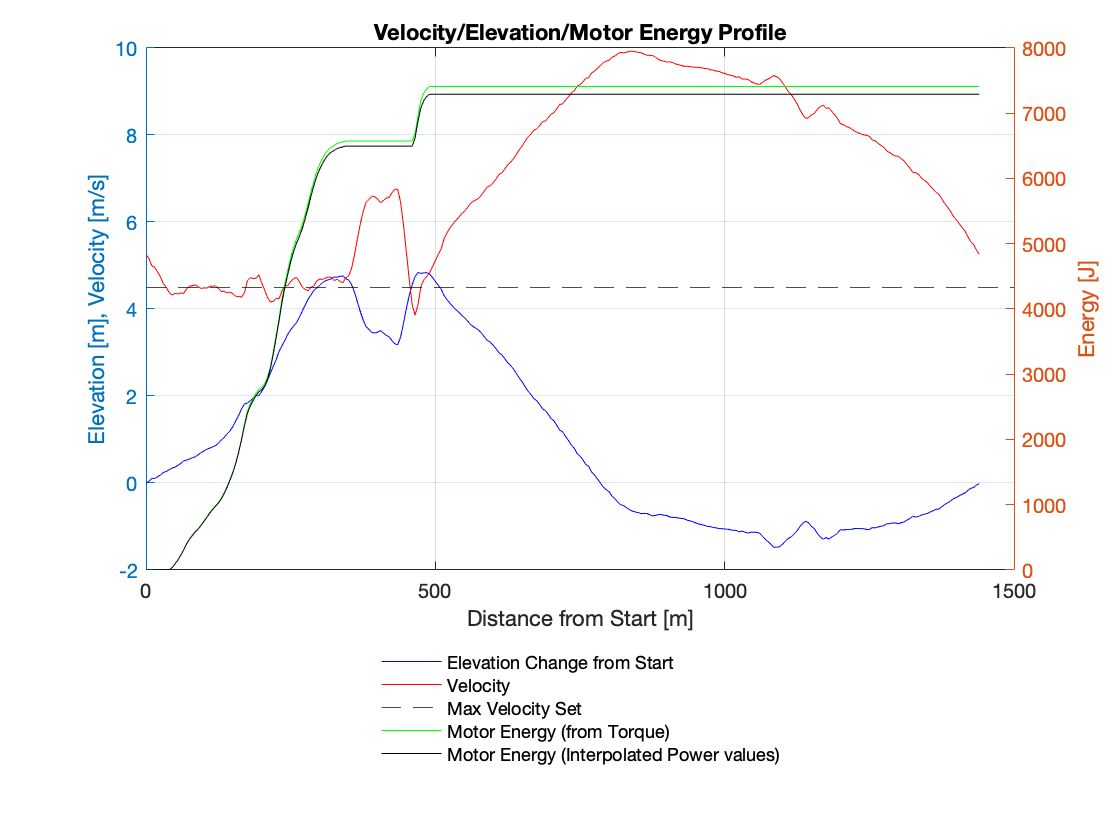

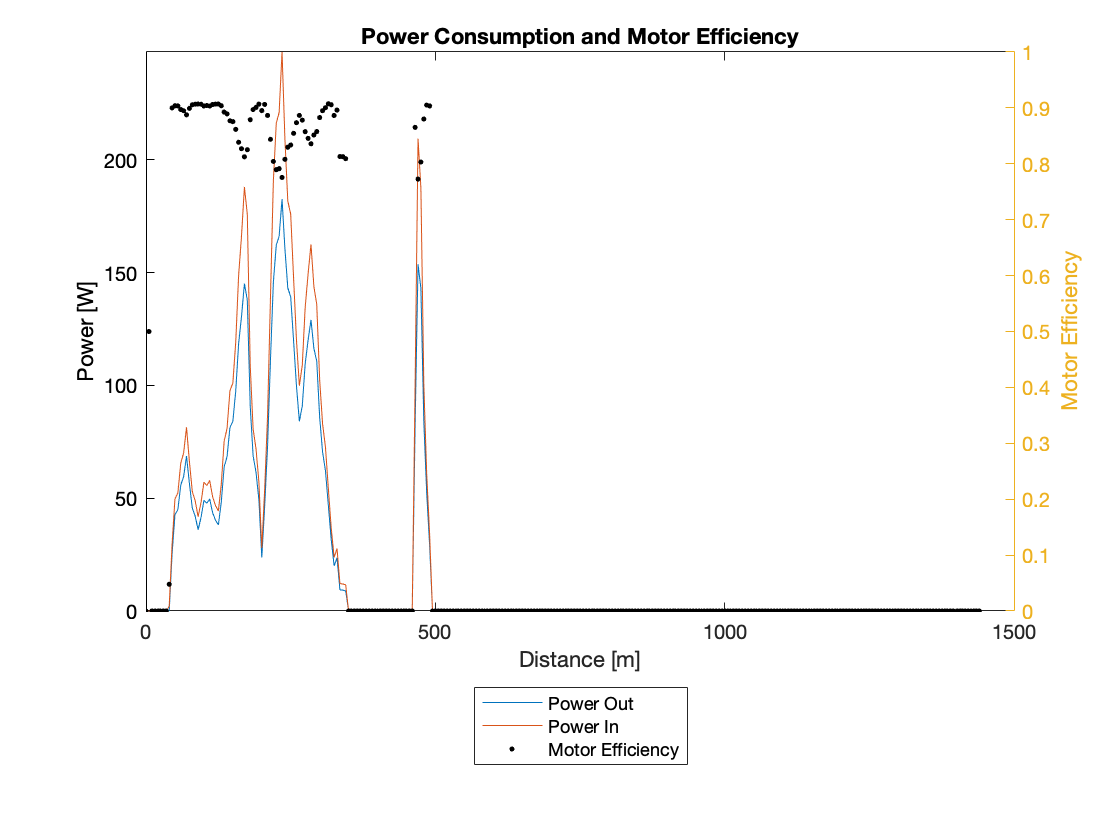

mileage1 = 415.9179

mileage2 = 419.2929

mileage3 = 416.7413

totalTime = 25.9214

brakeEnergy = 1.3699e+03

% Load Input Parameters
run Parameters.m;
S = load('FCV_Input.mat');
[mileage1, mileage2, mileage3, totalTime, brakeEnergy] = runFCV(S.max_velocity,0,S.brake_distance,S.initialOutput, S.plot_fig)

## FCV Monte Carlo Simulation

% Load Input Parameters
run Parameters.m;
S = load('FCV_Input.mat');
[T] = runFCVMC(S.maxV_mean, S.maxV_sd, S.brakeDist_mean, S.brakeDist_sd, S.initialOutput_mean, S.initialOutput_sd,S.numTrials,S.generateHistogram)